# **Tarea 1: Flujo de potencia en redes de distribución**

clc
clear
close all
load("datos_lineas.mat")
load("datos_nodos.mat")

Se estudiará el flujo de potencia en la red de 34 nodos, presentada en la Figura 1[.](about:blank<#_bookmark0%3E) Para esta red, suponiendo un sistema balanceado, se estudiará un equivalente monofásico, el cual incluye el detalle de los tramos de las líneas.

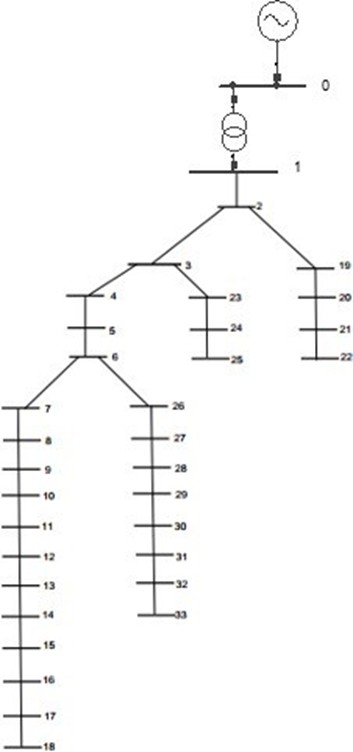

Figura 1. Sistema 34 nodos.

## Punto 3:

Utilizando el método escalera descrito en la clase, determine el flujo de potencia AC de la red, considerando las componentes resistivas y realizando la comparación con lo obtenido en el punto 2.

Para dar solución a este problema se deben crear los vectores correspondientes a los voltajes y corrientes de cada nodo. Para el método de la escalera en la primera iteración se asumen todos los voltajes con magnitud 1 y ángulo 0 para todos:

### Primer paso:

Para empezar se declaran las bases del sistema para poder convertir luego los datos a por unidad:

Vbase = 12.66; %KV
Sbase = 100; %MVA
Zbase = (Vbase^2)/Sbase;

### Segundo Paso:

Ya habiendo importado los datos, se pueden leer las tablas como matrices y normalizarlos con las bases anteriormente calculadas:

tabla_lineas = table2array(datos_lineas(:,:)); %Se pasa de tabla a matriz
tabla_nodos = table2array(datos_nodos(:,:)); %Se pasa de tabla a matriz

tabla_nodos(:,2:3) = tabla_nodos(:,2:3)/(Sbase*1000); %Se normalizan las potencias que están en KW
tabla_lineas(:,4:5) = tabla_lineas(:,4:5)/Zbase; %Se normalizan las impedancias con Zbase

### Tercer paso:

Ahora, se pueden hallar el número de nodos y lineas a tratar. Además se pueden esteblecer los vectores de voltajes iniciales (1's) y corrientes iniciales(0´s).

voltajes = ones(size(tabla_nodos,1),1);
voltajes(1) = 1;%*12.66/110; % Se sabe que el voltaje del nodo 1 corresponde a la salida del trasformador por lo que se aplica la reducción:
corrientes = zeros(size(tabla_lineas,1),1);
n_lineas = size(tabla_lineas,1);

### Cuarto paso:

Ahora, se pueden armar los vectores de los pares complejos de las potencias activas y las impedancias de las lineas:

Scargas = complex(tabla_nodos(:,2),tabla_nodos(:,3)); %P+jQ
Zlineas = complex(tabla_lineas(:,4),tabla_lineas(:,5)); %R+jX

### Quinto paso:

Empezar a iterar con los algorimos de Backward Sweep (para hallar las correintes) y Forward Sweep (para hallar los voltajes). Además de establecer un criterio de parada que sea un número de iteraciones máximo o una diferencia máxima de voltaje.

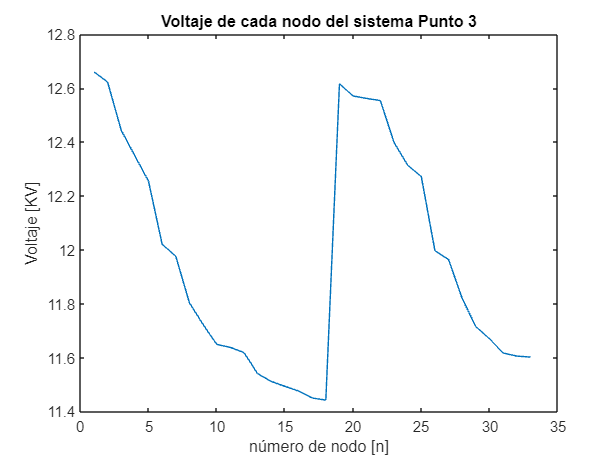

iterMax = 2000; %Máximo de iteraiones
dVlim = 0.0001; %Límite por encima de l máxima diferencia de voltajes

dVmax = 1; %Se inicializa el vector de diferencia mayor al límite

contador = 0;
while contador < iterMax && dVmax > dVlim
    %Backward Sweep...
    Icargas = conj(Scargas./voltajes); %Se calculan las corrientes generadas por las cargas en cada linea
    for j=n_lineas:-1:1
        [x,y] = find(tabla_lineas(:,2:3) == tabla_lineas(j,3)); %Se miran cuales de las conexiones es contiene el nodo de inicio de la iteración actual
        if size(x,1) == 1 %Si el size es 1 es porque es el principio o el final del tramo
            corrientes(tabla_lineas(j,1)) = Icargas(tabla_lineas(j,3)); %Por lo tanto la unica corriente asiganda es la de la carga
        else %En el caso contrario será la de las cargas en ese nodo más la suma de las corrientes que le entran menos las que le salen
            corrientes(tabla_lineas(j,1)) = Icargas(tabla_lineas(j,3)) + sum(corrientes(tabla_lineas(x,1))) - corrientes(tabla_lineas(j,1));
        end
    end
    
    volatajes_viejos = voltajes;
    %Forward Sweep...
    for j=1:n_lineas
        %Por último queda calcular el voltaje de cada nodo como el voltaje
        %del nodo anterior menos las perdidas de voltaje que se dan por la
        %corriente y la impedancia de la linea
        voltajes(tabla_lineas(j,3)) = voltajes(tabla_lineas(j,2)) - corrientes(tabla_lineas(j,1))*Zlineas(j);
    end
    contador = contador + 1;
    dVmax = max(abs(volatajes_viejos-voltajes));
end
voltages_mag = abs(voltajes);
voltages_ang = angle(voltajes);
voltages_mag_p3 = voltages_mag;

plot(voltages_mag*Vbase)
title("Voltaje de cada nodo del sistema Punto 3")
xlabel("número de nodo [n]")
ylabel("Voltaje [KV]")
exportgraphics(gcf,"p3.png","Resolution",600)

titles = ["nodo","V [KV]","theta [rad]","Ploss [KW]","Qloss [KVAR]"];

P = real(Zlineas.*(corrientes.^2));
Q = imag(Zlineas.*(corrientes.^2));

nodos = [0;tabla_nodos(:,1)];
voltajes_p3 = [110;voltages_mag*Vbase];
angulos = [0;voltages_ang];
P = [0;0;P*Sbase];
Q = [0;0;Q*Sbase];
resultados = table(nodos,voltajes_p3,angulos,P,Q,'VariableNames',titles);

%writetable(resultados,"resultados_p3.xlsx","WriteMode","overwrite","AutoFitWidth",false);

## Punto 4

### Agregando condensadores:

Aplicando el cambio de los condensadores:

nodos_condensadores = [3,7,10,13,16]';
datos_nodos_p3 = datos_nodos;
datos_nodos(nodos_condensadores,3) = datos_nodos(nodos_condensadores,3) - 50; %Se restan 50KW

### Primer paso:

Para empezar se declaran las bases del sistema para poder convertir luego los datos a por unidad:

Vbase = 12.66; %KV
Sbase = 100; %MVA
Zbase = (Vbase^2)/Sbase;

### Segundo Paso:

Ya habiendo importado los datos, se pueden leer las tablas como matrices y normalizarlos con las bases anteriormente calculadas:

tabla_lineas = table2array(datos_lineas(:,:)); %Se pasa de tabla a matriz
tabla_nodos = table2array(datos_nodos(:,:)); %Se pasa de tabla a matriz

tabla_nodos(:,2:3) = tabla_nodos(:,2:3)/(Sbase*1000); %Se normalizan las potencias que están en KW
tabla_lineas(:,4:5) = tabla_lineas(:,4:5)/Zbase; %Se normalizan las impedancias con Zbase

### Tercer paso:

Ahora, se pueden hallar el número de nodos y lineas a tratar. Además se pueden esteblecer los vectores de voltajes iniciales (1's) y corrientes iniciales(0´s).

voltajes = ones(size(tabla_nodos,1),1);
voltajes(1) = 1;%*12.66/110; % Se sabe que el voltaje del nodo 1 corresponde a la salida del trasformador por lo que se aplica la reducción:
corrientes = zeros(size(tabla_lineas,1),1);
n_lineas = size(tabla_lineas,1);

### Cuarto paso:

Ahora, se pueden armar los vectores de los pares complejos de las potencias activas y las impedancias de las lineas:

Scargas = complex(tabla_nodos(:,2),tabla_nodos(:,3)); %P+jQ
Zlineas = complex(tabla_lineas(:,4),tabla_lineas(:,5)); %R+jX

### Quinto paso:

Empezar a iterar con los algorimos de Backward Sweep (para hallar las correintes) y Forward Sweep (para hallar los voltajes). Además de establecer un criterio de parada que sea un número de iteraciones máximo o una diferencia máxima de voltaje.

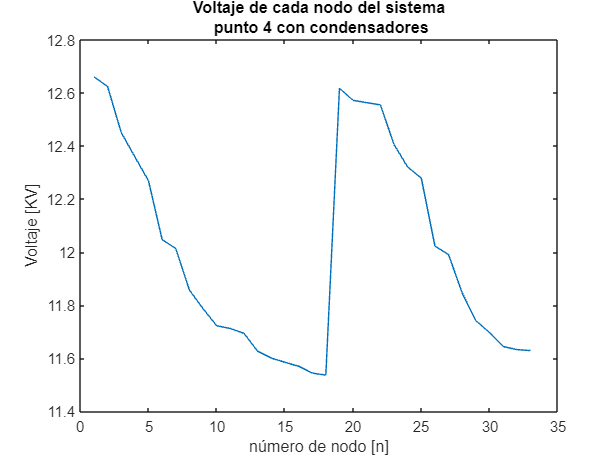

iterMax = 2000; %Máximo de iteraiones
dVlim = 0.0001; %Límite por encima de l máxima diferencia de voltajes

dVmax = 1; %Se inicializa el vector de diferencia mayor al límite

contador = 0;
while contador < iterMax && dVmax > dVlim
    %Backward Sweep...
    Icargas = conj(Scargas./voltajes); %Se calculan las corrientes generadas por las cargas en cada linea
    for j=n_lineas:-1:1
        [x,y] = find(tabla_lineas(:,2:3) == tabla_lineas(j,3)); %Se miran cuales de las conexiones es contiene el nodo de inicio de la iteración actual
        if size(x,1) == 1 %Si el size es 1 es porque es el principio o el final del tramo
            corrientes(tabla_lineas(j,1)) = Icargas(tabla_lineas(j,3)); %Por lo tanto la unica corriente asiganda es la de la carga
        else %En el caso contrario será la de las cargas en ese nodo más la suma de las corrientes que le entran menos las que le salen
            corrientes(tabla_lineas(j,1)) = Icargas(tabla_lineas(j,3)) + sum(corrientes(tabla_lineas(x,1))) - corrientes(tabla_lineas(j,1));
        end
    end
    
    volatajes_viejos = voltajes;
    %Forward Sweep...
    for j=1:n_lineas
        %Por último queda calcular el voltaje de cada nodo como el voltaje
        %del nodo anterior menos las perdidas de voltaje que se dan por la
        %corriente y la impedancia de la linea
        voltajes(tabla_lineas(j,3)) = voltajes(tabla_lineas(j,2)) - corrientes(tabla_lineas(j,1))*Zlineas(j);
    end
    contador = contador + 1;
    dVmax = max(abs(volatajes_viejos-voltajes));
end
voltages_mag = abs(voltajes);
voltages_ang = angle(voltajes);
voltages_mag_p4_1 = voltages_mag;
plot(voltages_mag*Vbase)
title({"Voltaje de cada nodo del sistema";" punto 4 con condensadores"})
xlabel("número de nodo [n]")
ylabel("Voltaje [KV]")
exportgraphics(gcf,"p41.png","Resolution",600)

titles = ["nodo","V [KV]","theta [rad]","Ploss [KW]","Qloss [KVAR]"];

P = real(Zlineas.*(corrientes.^2));
Q = imag(Zlineas.*(corrientes.^2));

nodos = [0;tabla_nodos(:,1)];
voltajes_p4 = [110;voltages_mag*Vbase];
angulos = [0;voltages_ang];
P = [0;0;P*Sbase];
Q = [0;0;Q*Sbase];
resultados_p4 = table(nodos,voltajes_p4,angulos,P,Q,'VariableNames',titles);

%writetable(resultados_p4,"resultados_p4.xlsx","WriteMode","overwrite","AutoFitWidth",false);

### Agregando Cargas Sincronicas:

nodos_sincronicas = [18,33,25,22]';
cargas_sincronicas = [100,100,450,100]'; %KW
datos_nodos_viejos = datos_nodos;
datos_nodos(nodos_sincronicas,2) = datos_nodos(nodos_sincronicas,2) - cargas_sincronicas; 

### Primer paso:

Para empezar se declaran las bases del sistema para poder convertir luego los datos a por unidad:

Vbase = 12.66; %KV
Sbase = 100; %MVA
Zbase = (Vbase^2)/Sbase;

### Segundo Paso:

Ya habiendo importado los datos, se pueden leer las tablas como matrices y normalizarlos con las bases anteriormente calculadas:

tabla_lineas = table2array(datos_lineas(:,:)); %Se pasa de tabla a matriz
tabla_nodos = table2array(datos_nodos(:,:)); %Se pasa de tabla a matriz

tabla_nodos(:,2:3) = tabla_nodos(:,2:3)/(Sbase*1000); %Se normalizan las potencias que están en KW
tabla_lineas(:,4:5) = tabla_lineas(:,4:5)/Zbase; %Se normalizan las impedancias con Zbase

### Tercer paso:

Ahora, se pueden hallar el número de nodos y lineas a tratar. Además se pueden esteblecer los vectores de voltajes iniciales (1's) y corrientes iniciales(0´s).

voltajes = ones(size(tabla_nodos,1),1);
voltajes(1) = 1;%*12.66/110; % Se sabe que el voltaje del nodo 1 corresponde a la salida del trasformador por lo que se aplica la reducción:
corrientes = zeros(size(tabla_lineas,1),1);

n_nodos = size(tabla_nodos,1);
n_lineas = size(tabla_lineas,1);

### Cuarto paso:

Ahora, se pueden armar los vectores de los pares complejos de las potencias activas y las impedancias de las lineas:

Scargas = complex(tabla_nodos(:,2),tabla_nodos(:,3)); %P+jQ
Zlineas = complex(tabla_lineas(:,4),tabla_lineas(:,5)); %R+jX

### Quinto paso:

Empezar a iterar con los algorimos de Backward Sweep (para hallar las correintes) y Forward Sweep (para hallar los voltajes). Además de establecer un criterio de parada que sea un número de iteraciones máximo o una diferencia máxima de voltaje.

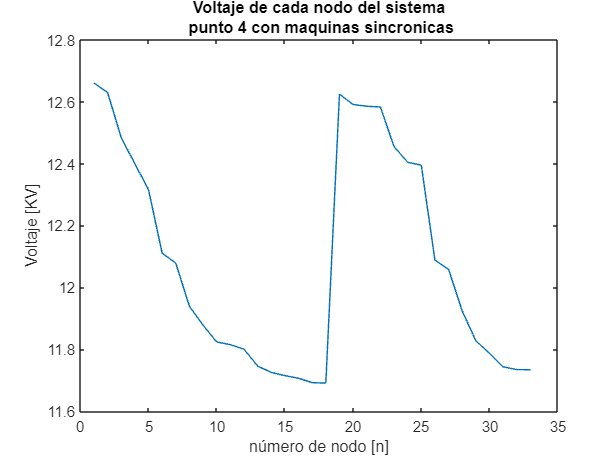

iterMax = 2000; %Máximo de iteraiones
dVlim = 0.0001; %Límite por encima de l máxima diferencia de voltajes

dVmax = 1; %Se inicializa el vector de diferencia mayor al límite

contador = 0;
while contador < iterMax && dVmax > dVlim
    %Backward Sweep...
    Icargas = conj(Scargas./voltajes); %Se calculan las corrientes generadas por las cargas en cada linea
    for j=n_lineas:-1:1
        [x,y] = find(tabla_lineas(:,2:3) == tabla_lineas(j,3)); %Se miran cuales de las conexiones es contiene el nodo de inicio de la iteración actual
        if size(x,1) == 1 %Si el size es 1 es porque es el principio o el final del tramo
            corrientes(tabla_lineas(j,1)) = Icargas(tabla_lineas(j,3)); %Por lo tanto la unica corriente asiganda es la de la carga
        else %En el caso contrario será la de las cargas en ese nodo más la suma de las corrientes que le entran menos las que le salen
            corrientes(tabla_lineas(j,1)) = Icargas(tabla_lineas(j,3)) + sum(corrientes(tabla_lineas(x,1))) - corrientes(tabla_lineas(j,1));
        end
    end
    
    volatajes_viejos = voltajes;
    %Forward Sweep...
    for j=1:n_lineas
        %Por último queda calcular el voltaje de cada nodo como el voltaje
        %del nodo anterior menos las perdidas de voltaje que se dan por la
        %corriente y la impedancia de la linea
        voltajes(tabla_lineas(j,3)) = voltajes(tabla_lineas(j,2)) - corrientes(tabla_lineas(j,1))*Zlineas(j);
    end
    contador = contador + 1;
    dVmax = max(abs(volatajes_viejos-voltajes));
end
voltages_mag = abs(voltajes);
voltages_ang = angle(voltajes);
voltages_mag_p4_2 = voltages_mag;

plot(voltages_mag*Vbase)
title({"Voltaje de cada nodo del sistema";" punto 4 con maquinas sincronicas"})
xlabel("número de nodo [n]")
ylabel("Voltaje [KV]")
exportgraphics(gcf,"p42.png","Resolution",600)

titles = ["nodo","V [KV]","theta [rad]","Ploss [KW]","Qloss [KVAR]"];

P = real(Zlineas.*(corrientes.^2));
Q = imag(Zlineas.*(corrientes.^2));

nodos = [0;tabla_nodos(:,1)];
voltajes_p4 = [110;voltages_mag*Vbase];
angulos = [0;voltages_ang];
P = [0;0;P*Sbase];
Q = [0;0;Q*Sbase];
resultados_p41 = table(nodos,voltajes_p4,angulos,P,Q,'VariableNames',titles);

### Comparación del cambio en voltajes de cada punto

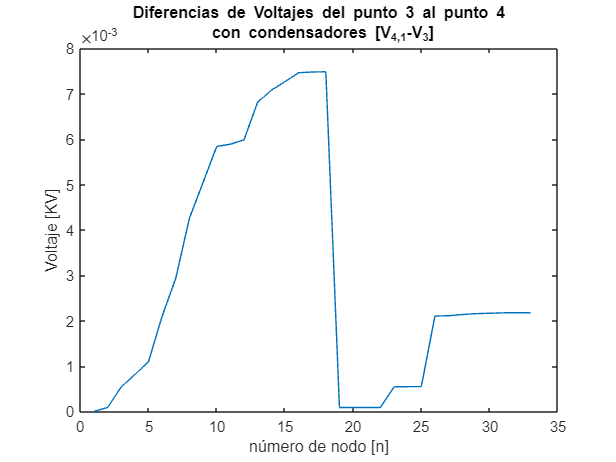

plot(voltages_mag_p4_1-voltages_mag_p3)
title({"Diferencias de Voltajes del punto 3 al punto 4";" con condensadores [V_{4,1}-V_3]"})
xlabel("número de nodo [n]")
ylabel("Voltaje [KV]")
exportgraphics(gcf,"p41m3.png","Resolution",600)

Como se puede observar en todo momento los la diferencia de voltajes al agregar los condensadores es positiva. Por otro lado, al agregar las maquinas sincrónicas adicional al agregar los condensadores también aumenta el voltaje como se puede observar en la siguiente gráfica:

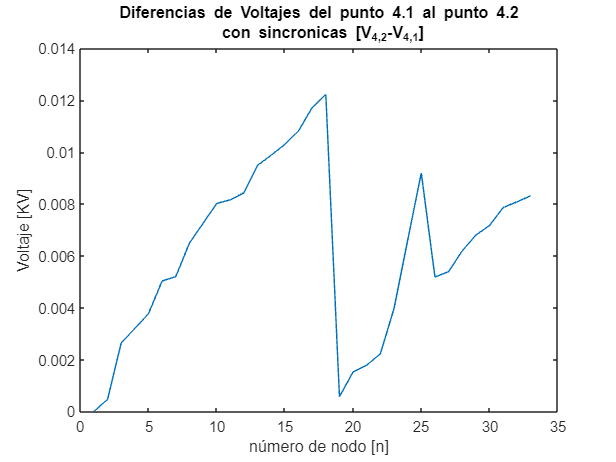

plot(voltages_mag_p4_2-voltages_mag_p4_1)
title({"Diferencias de Voltajes del punto 4.1 al punto 4.2";" con sincronicas [V_{4,2}-V_{4,1}]"})
xlabel("número de nodo [n]")
ylabel("Voltaje [KV]")
exportgraphics(gcf,"p42m41.png","Resolution",600)